a) Determine por simulacao a probabilidade de haver pelo menos uma colisao (pelo menos 2 keys mapeadas pela funcao de hash para a mesma posicao do array) se forem introduzidas 10 keys num array de tamanho T = 1000

E = 1e4;
T = 1000;
k = 10;

map = randi(T,k,E);
%disp(map);
suc = 0;
for a = 1:E
    col = map(:,a);
    aux = unique(col);
    if length(aux) < k
        suc = suc + 1;
    end
end
prob = suc/E;
display(prob);

b) Faca um grafico da probabilidade da alinea (a) em funcao do numero de keys para todos os valores relevantes num array de tamanho T = 1000

E = 1e4;
T = 1000;
k = 1:1:1000;
num = zeros(1,1000);

for k1 = k
    map = randi(T,k1,E);
    %disp(map);
    suc = 0;
    for a = 1:E
        col = map(:,a);
        aux = unique(col);
        if length(aux) < k1
            suc = suc + 1;
        end
    end
    prob = suc/E;
    num(k1) = prob;
end
plot(k, num);

c) Para um numero de keys igual a 50, represente graficamente a variacao da probabilidade (estimada por simulacao) de nao haver nenhuma colisao em funcao do tamanha T do array (assuma os tamanhos de 100 ate 1000 com incrementos de 100)

E = 1e4;
T = 100:100:1000;
k = 50;
num = zeros(1,10);

for t1 = T
    map = randi(t1,k,E);
    %disp(map);
    suc = 0;
    for a = 1:E
        col = map(:,a);
        aux = unique(col);
        if length(aux) < k
            suc = suc + 1;
        end
    end
    prob = 1-(suc/E);
    num(t1/100) = prob;
end
display(num);

num =          0    0.0012    0.0125    0.0440    0.0790    0.1253    0.1654    0.2087    0.2498    0.2848


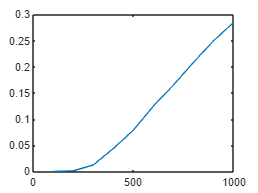

plot(T, num);